# MÉTODO DIFERENCIAS DIVIDIDAS NEWTON-RAPHSON

%datos de entrada
xi= [2 2.2 2.4 2.6 2.8];
%f=@(x) sin(x);
%fi = f(xi);
fi= [0.5103757 0.5207843 0.5104147 0.4813306 0.4359160];
n=length(xi);
dd=zeros(n); %reservamos espacio
dd(:,1)=fi    %sabemos que la primera columna de la matrizserán las imágenes de los puntos

dd =    0.510375700000000                   0                   0                   0                   0
   0.520784300000000                   0                   0                   0                   0
   0.510414700000000                   0                   0                   0                   0
   0.481330600000000                   0                   0                   0                   0
   0.435916000000000                   0                   0                   0                   0



%matriz de diferencias divididas:
for j=2:n
    for i=1:n-j+1
        dd(i,j)=(dd(i+1,j-1)-dd(i,j-1))/(xi(i+j-1)-xi(i));
    end
end
dd

dd =    0.510375700000000   0.052043000000000  -0.259727500000000   0.042993750000000   0.008341145833332
   0.520784300000000  -0.051848000000000  -0.233931250000000   0.049666666666665                   0
   0.510414700000000  -0.145420500000000  -0.204131250000001                   0                   0
   0.481330600000000  -0.227073000000000                   0                   0                   0
   0.435916000000000                   0                   0                   0                   0


ai=dd(1,:);

for i=1:length(ai)

    fprintf('a%d = %d \n',(i-1),ai(i));

end

a0 = 5.103757e-01 
a1 = 5.204300e-02 
a2 = -2.597275e-01 
a3 = 4.299375e-02 
a4 = 8.341146e-03 


si quiero dibujarlo

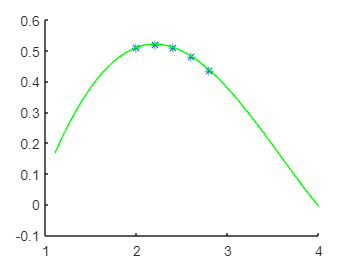


x = 1.1:0.001:4; %puntos en los que obtener el polinomio p evaluado


p = 0*x;
q = 1;

for i=1:n
        p = p + ai(i).*q; %construcción p 
        q = q.*(x-xi(i)); 
end

hold on 
plot(xi,fi, '*')  %representar datos dados
%plot(x,f(x),'b') %representar función 
plot(x,p,'g') %representar polinomio interpolador

% xlim([2 2.8])
% ylim([0.4 0.6])